TP 1 Signal : TNS TP1

clear all
close all

load('sigEcgFile.mat')
load('sigEcgFile2.mat')

%N1 = length(sigEcgFile);
N2 = length(sigEcgFile2);
Nfft1 = 128;
Nfft2 = 256;
Nfft3 = 1024;


Nu0 = 0.37;
b = 2;
b2 = 10;
b3 = 50;
b4 = 1000;


% plot(sigEcgFile)
% title("ECGs temporels")
% xlabel("Echantillons n")
% ylabel("Amplitude")
% 
% hold on

% plot(sigEcgFile2)
% %title("ECG2")
% %xlabel("Echantillons n")
% %ylabel("Amplitude")
% 
% legend("ECG1", "ECG2")
% 
% 
% hold off

%[vectNu1, I1] = spectrogramme(sigEcgFile);
% [vectNuNfft1, INfft1] = spectrogramme(sigEcgFile2, Nfft1);
% [vectNuNfft2, INfft2] = spectrogramme(sigEcgFile2, Nfft2);
% [vectNuNfft3, INfft3] = spectrogramme(sigEcgFile2, Nfft3);
% %Idb2 = 10*log(I2);
% 
% plot(vectNuNfft1, INfft1)
% title("Spectrogrammes de ECG2 avec Nfft")
% 
% xlabel("fréquence réduite Nu")
% ylabel("Amplitude en Hz")
% 
% hold on
% 
% plot(vectNuNfft2, INfft2)
% 
% plot(vectNuNfft3, INfft3)
% 
% legend("Nfft = 128", "Nfft = 256", "Nfft = 1024")
% hold off

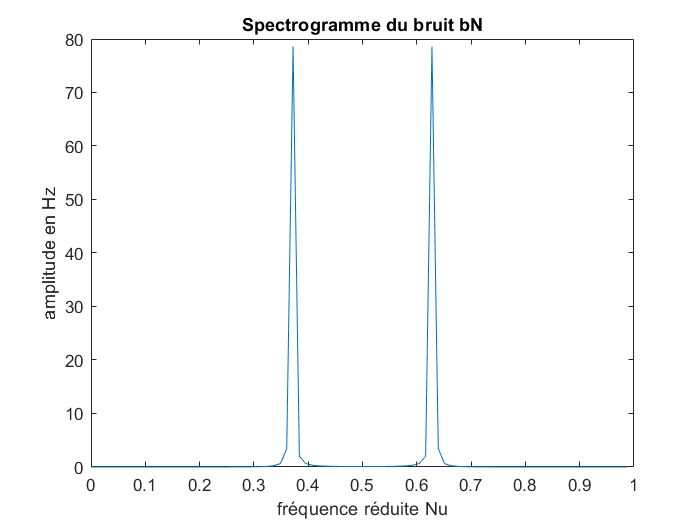

[vectN2, bN] = ajoutBruitN(b, Nu0, N2);
[vectNu2, IbN] = spectrogramme(bN, N2);

plot(vectNu2, IbN)
title("Spectrogramme du bruit bN")
xlabel("fréquence réduite Nu")
ylabel("amplitude en Hz")

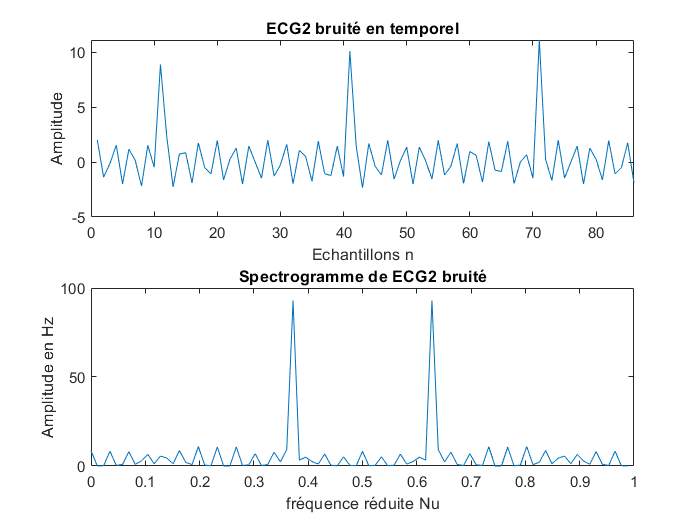

ECG2avecBruit = sigEcgFile2 + bN;
[vectNu2b, Iecg2bruit] = spectrogramme(ECG2avecBruit, N2);

subplot(211)
plot(ECG2avecBruit)
title("ECG2 bruité en temporel")
xlabel("Echantillons n")
ylabel("Amplitude")
xlim([0,86])

subplot(212)
plot(vectNu2b, Iecg2bruit)
title("Spectrogramme de ECG2 bruité")
xlabel("fréquence réduite Nu")
ylabel("Amplitude en Hz")

[Pecg2] = Puissance(sigEcgFile2)

Pecg2 = 3.1862

[Pbruit] = Puissance(bN)

Pbruit = 2.0275

RSB1 = Pecg2/Pbruit;
RSBdb1 = 10*log(RSB1)

RSBdb1 = 4.5204



[vectN2, bN2] = ajoutBruitN(b2, Nu0, N2);
[Pbruit2] = Puissance(bN2);
RSB2 = Pecg2/Pbruit2;
RSBdb2 = 10*log(RSB2)

RSBdb2 = -27.6683



[vectN2, bN3] = ajoutBruitN(b3, Nu0, N2);
[Pbruit3] = Puissance(bN3);
RSB3 = Pecg2/Pbruit3;
RSBdb3 = 10*log(RSB3)

RSBdb3 = -59.8571